# Example 4

#### Problem OCP:


$$\min_{{x}(t),{u}(t),t_f} t_f$$


subject to:


$$
 \dot{{x}_1}(t) = x_3(t)   \quad \dot{{x}_3}(t) = u_1(t), $$



$$
 \dot{{x}_2}(t) = x_4(t)   \quad \dot{{x}_4}(t) = u_2(t), $$



$$x_1(0) = 0, \quad x_2(0) = 0, \quad x_3(0) = 0, \quad x_4(0) = 0, $$



$$x_1(t_f) = 10, \quad x_2(t_f) = 10, \quad x_3(t_f) = 0, \quad x_4(t_f) = 0, $$



$$\sqrt{u_1(t)^2+u_2(t)^2} \leq a_{max} 
$$



$$\sqrt{x_3(t)^2+x_4(t)^2} \leq v_{max}
$$


## Implementation:

clear all
close all

### Load Parameters

CONSTANTS.N = 10;
CONSTANTS.x10 = 0;
CONSTANTS.x20 = 0;
CONSTANTS.x30 = 0;
CONSTANTS.x40 = 0;
CONSTANTS.x1f = 10;
CONSTANTS.x2f = 10;
CONSTANTS.x3f = 0;
CONSTANTS.x4f = 3;
CONSTANTS.amax = 5;
CONSTANTS.vmax = 5;

### Initial Guess

N = CONSTANTS.N; 
x1 = linspace(CONSTANTS.x10,CONSTANTS.x1f,CONSTANTS.N+1)';
x2 = linspace(CONSTANTS.x20,CONSTANTS.x2f,CONSTANTS.N+1)';
x3 = linspace(CONSTANTS.x30,CONSTANTS.x3f,CONSTANTS.N+1)';
x4 = linspace(CONSTANTS.x40,CONSTANTS.x4f,CONSTANTS.N+1)';
u1 = ones(N+1,1);
u2 = ones(N+1,1);
tf = 1;
x0 = [x1;x2;x3;x4;u1;u2;tf];

### Linear Constraints and UL bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

### Optimize (fmincon)

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',300000);
tic
[x,f] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 0.381642 seconds.


### Plot

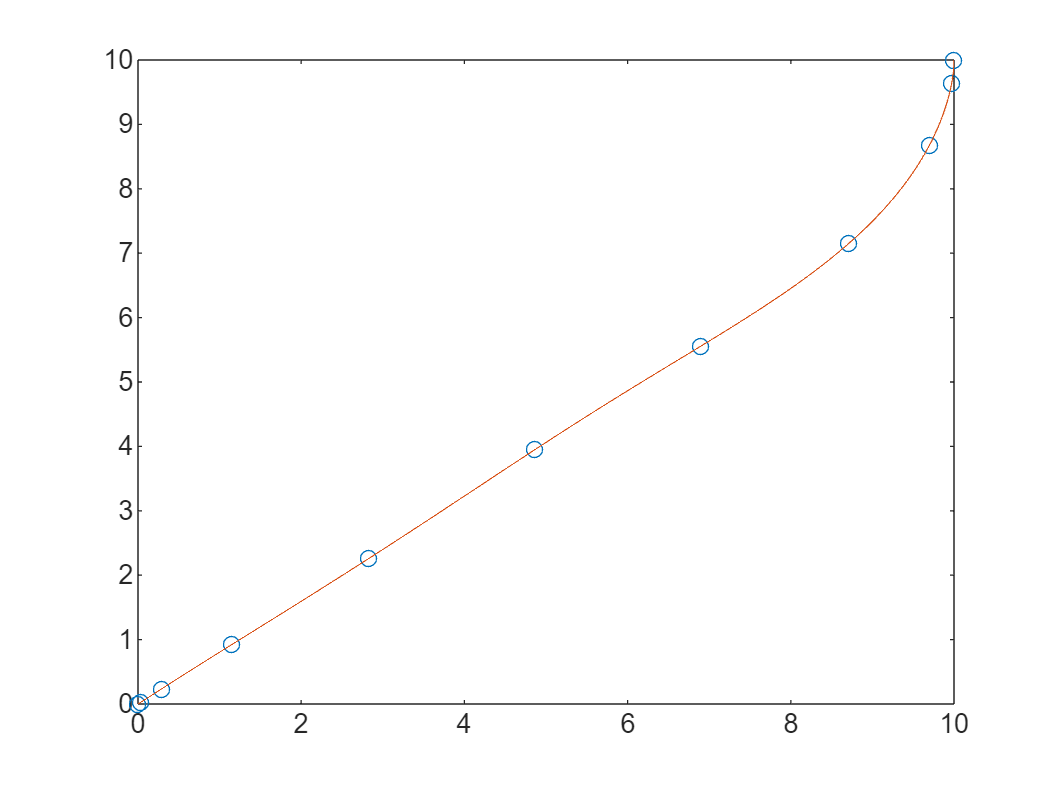

N = CONSTANTS.N;
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
u1 = x(4*N+5:5*N+5);
u2 = x(5*N+6:6*N+6);
tf = x(end);


[tnodes,w,Diff] = LGL_PS(CONSTANTS.N,tf);
t = 0:0.001:tf;

figure
plot(x1,x2,'o'); hold on
plot(LagrangePoly(x1,tnodes,t),LagrangePoly(x2,tnodes,t));

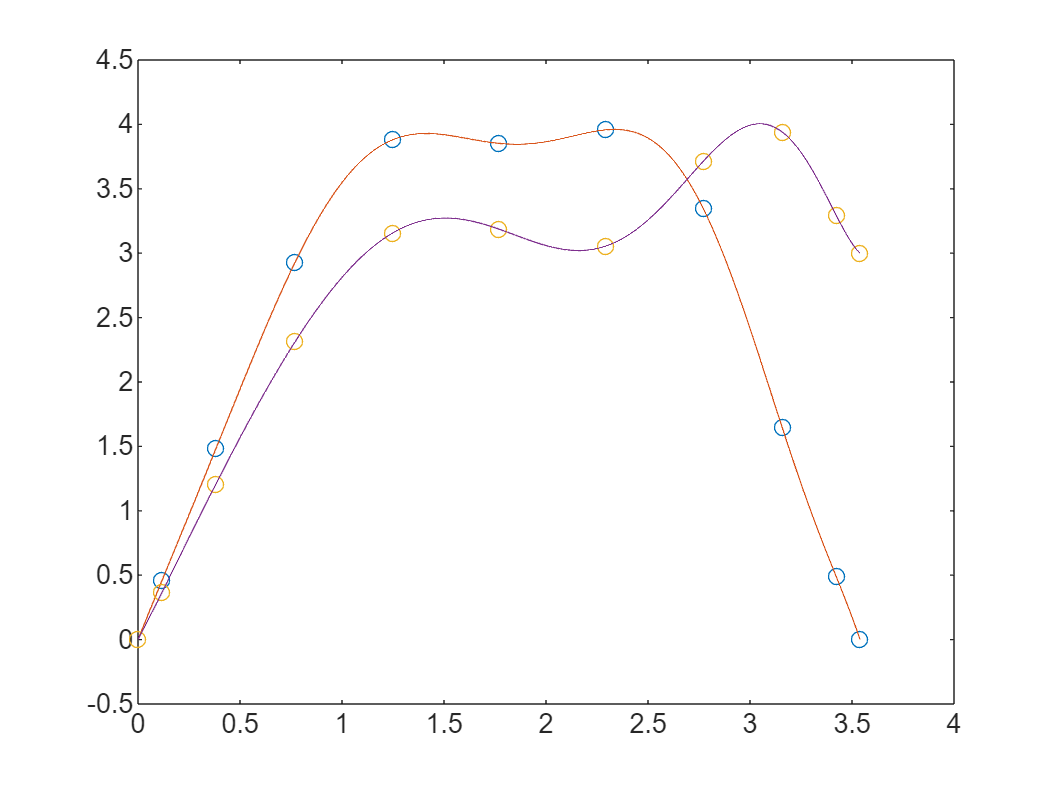

figure
plot(tnodes,x3,'o'); hold on
plot(t,LagrangePoly(x3,tnodes,t)); 
plot(tnodes,x4,'o'); hold on
plot(t,LagrangePoly(x4,tnodes,t)); 

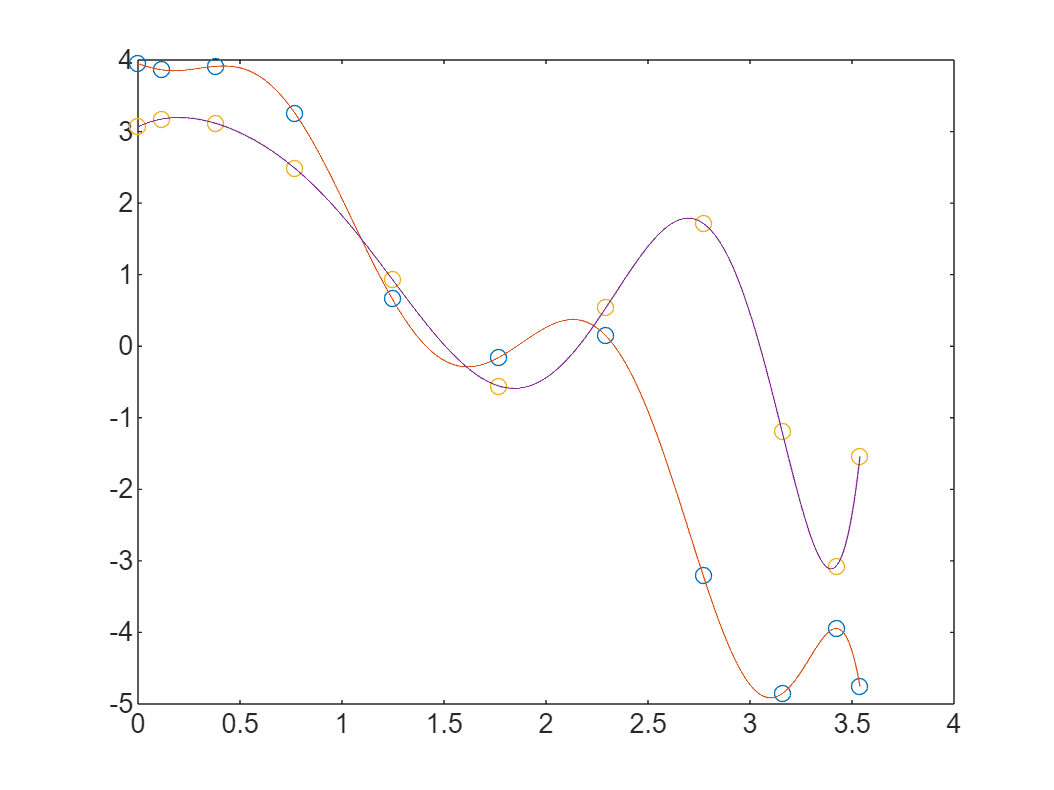


figure
plot(tnodes,u1,'o'); hold on
plot(t,LagrangePoly(u1,tnodes,t)); 
plot(tnodes,u2,'o'); hold on
plot(t,LagrangePoly(u2,tnodes,t));

### Cost function

function J = costfun(x,CONSTANTS)
%COSTFUN Summary of this function goes here
N = CONSTANTS.N; 

N = CONSTANTS.N;
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
u1 = x(4*N+5:5*N+5);
u2 = x(5*N+6:6*N+6);
tf = x(end);

J = tf;
end

### Nonlinear Constraint

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N; 

N = CONSTANTS.N;
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
u1 = x(4*N+5:5*N+5);
u2 = x(5*N+6:6*N+6);
tf = x(end);

[~,~,Diff] = LGL_PS(CONSTANTS.N,tf);

dyn1 = x1'*Diff-x3';
dyn2 = x3'*Diff-u1';
dyn3 = x2'*Diff-x4';
dyn4 = x4'*Diff-u2';

IC1 = x1(1) - CONSTANTS.x10;
IC2 = x2(1) - CONSTANTS.x20;
IC3 = x3(1) - CONSTANTS.x30;
IC4 = x4(1) - CONSTANTS.x40;
FC1 = x1(end) - CONSTANTS.x1f;
FC2 = x2(end) - CONSTANTS.x2f;
FC3 = x3(end) - CONSTANTS.x3f;
FC4 = x4(end) - CONSTANTS.x4f;

nonlcon1 = u1.^2+u2.^2 - CONSTANTS.amax^2;
nonlcon2 = x3.^2+x4.^2 - CONSTANTS.vmax^2;

c=[nonlcon1 ; nonlcon2;];
ceq=[dyn1'; dyn2'; dyn3'; dyn4'; IC1;IC2;IC3;IC4;FC1;FC2;FC3;FC4];
end